clear
load 20210305-RC_Chirp40v150kHz_T2s.mat
A1=A;
B1=B;
N=Length;
dt=Tinterval

dt = 1.0000e-06

fs=1/dt

fs = 1.0000e+06

load 20220401-RLC_Chirp1v300kHz_T2s.mat
A2=A;
B2=B;


R1=47;
C1=2.2e-6;

R2=220;
C2=4.7e-6;
L2=1e-3;

num1=1/(R1*C1)

num1 = 9.6712e+03

den1=[1 num1]

den1 = 1.0e+03 *

    0.0010    9.6712


sys=tf(num1,den1)


sys =
 
    9671
  --------
  s + 9671
 
Continuous-time transfer function.
Model Properties



num2=[R2/L2 0]

num2 =       220000           0


den2=[1 R2/L2 1/(C2*L2)]

den2 = 1.0e+08 *

    0.0000    0.0022    2.1277


sys2=tf(num2,den2)


sys2 =
 
          220000 s
  -------------------------
  s^2 + 220000 s + 2.128e08
 
Continuous-time transfer function.
Model Properties


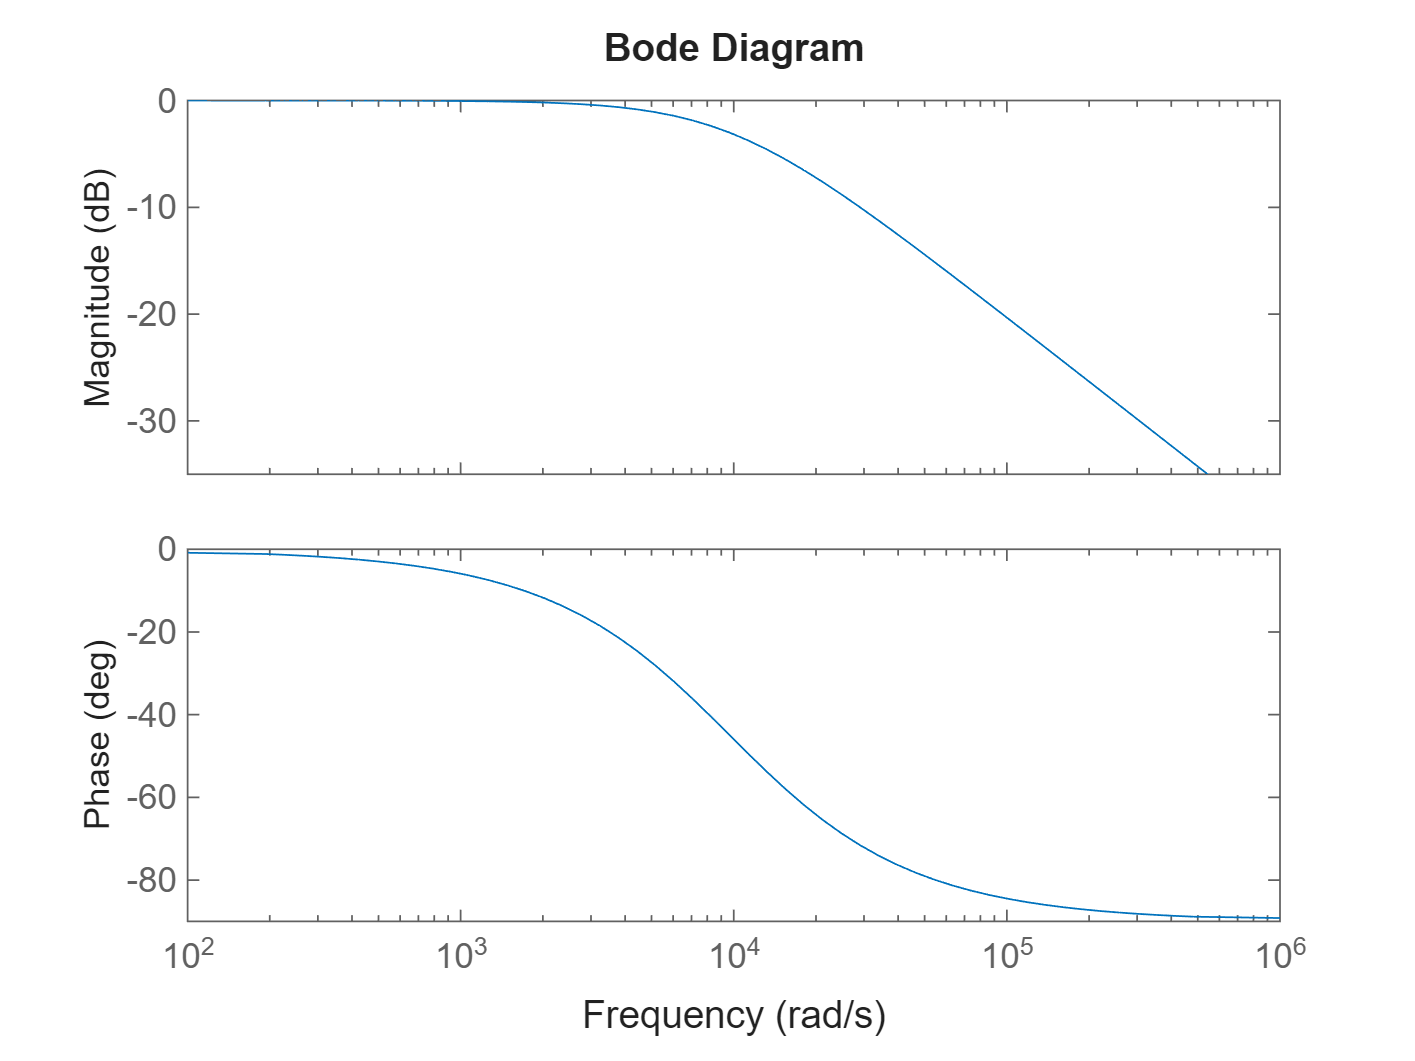


bode(sys)

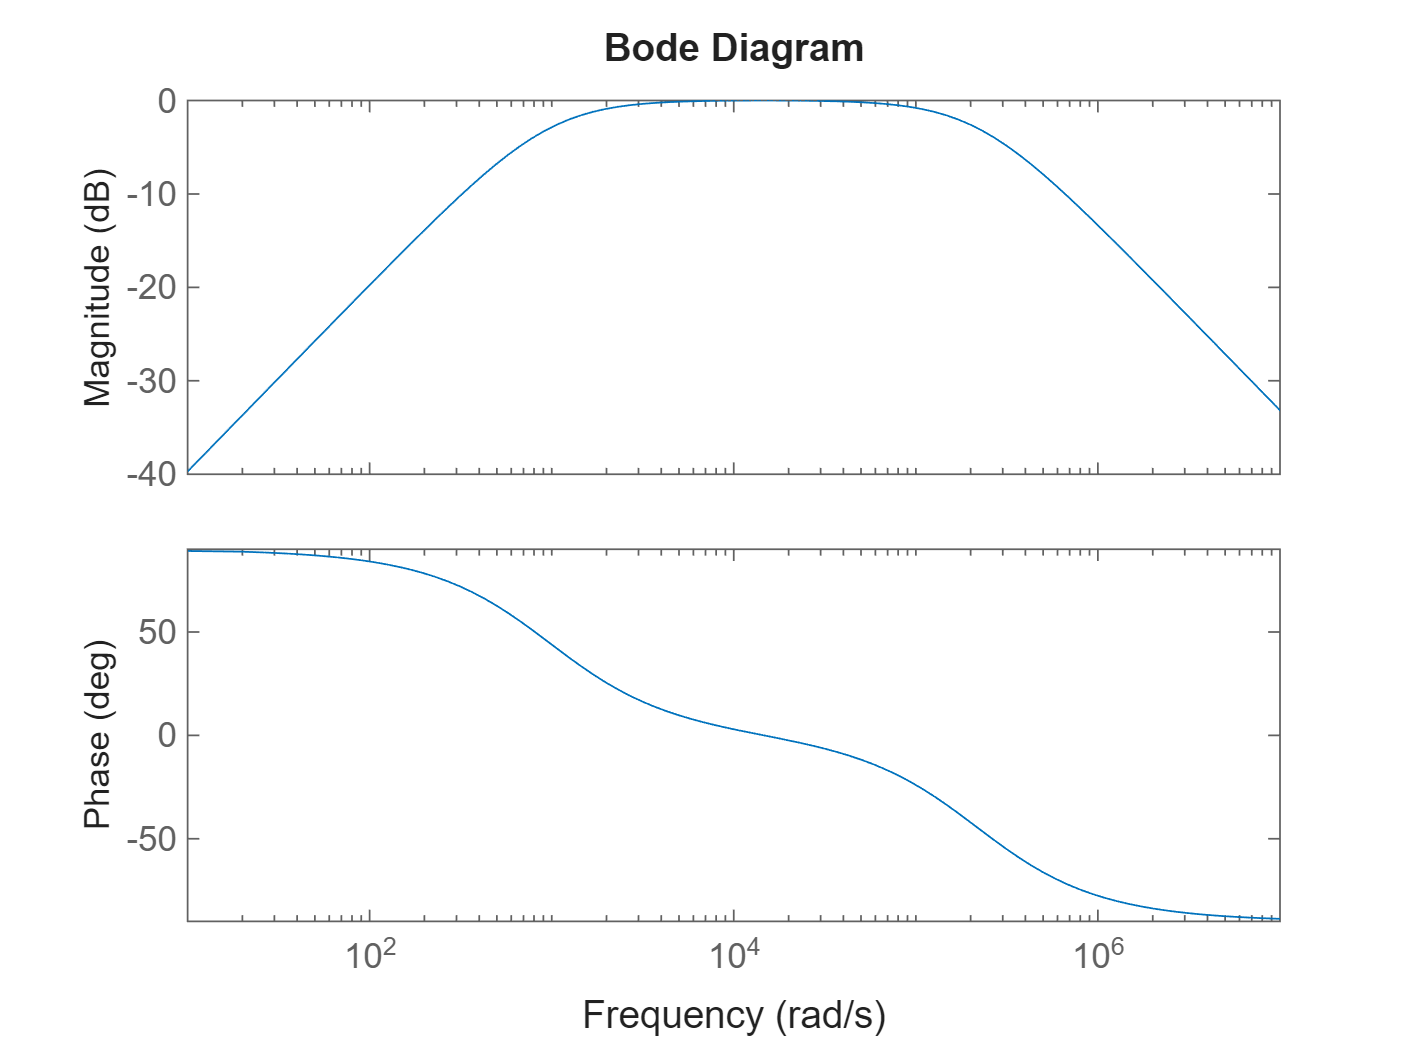

bode(sys2)

Creating system response Y(w) for chirp input V(w)

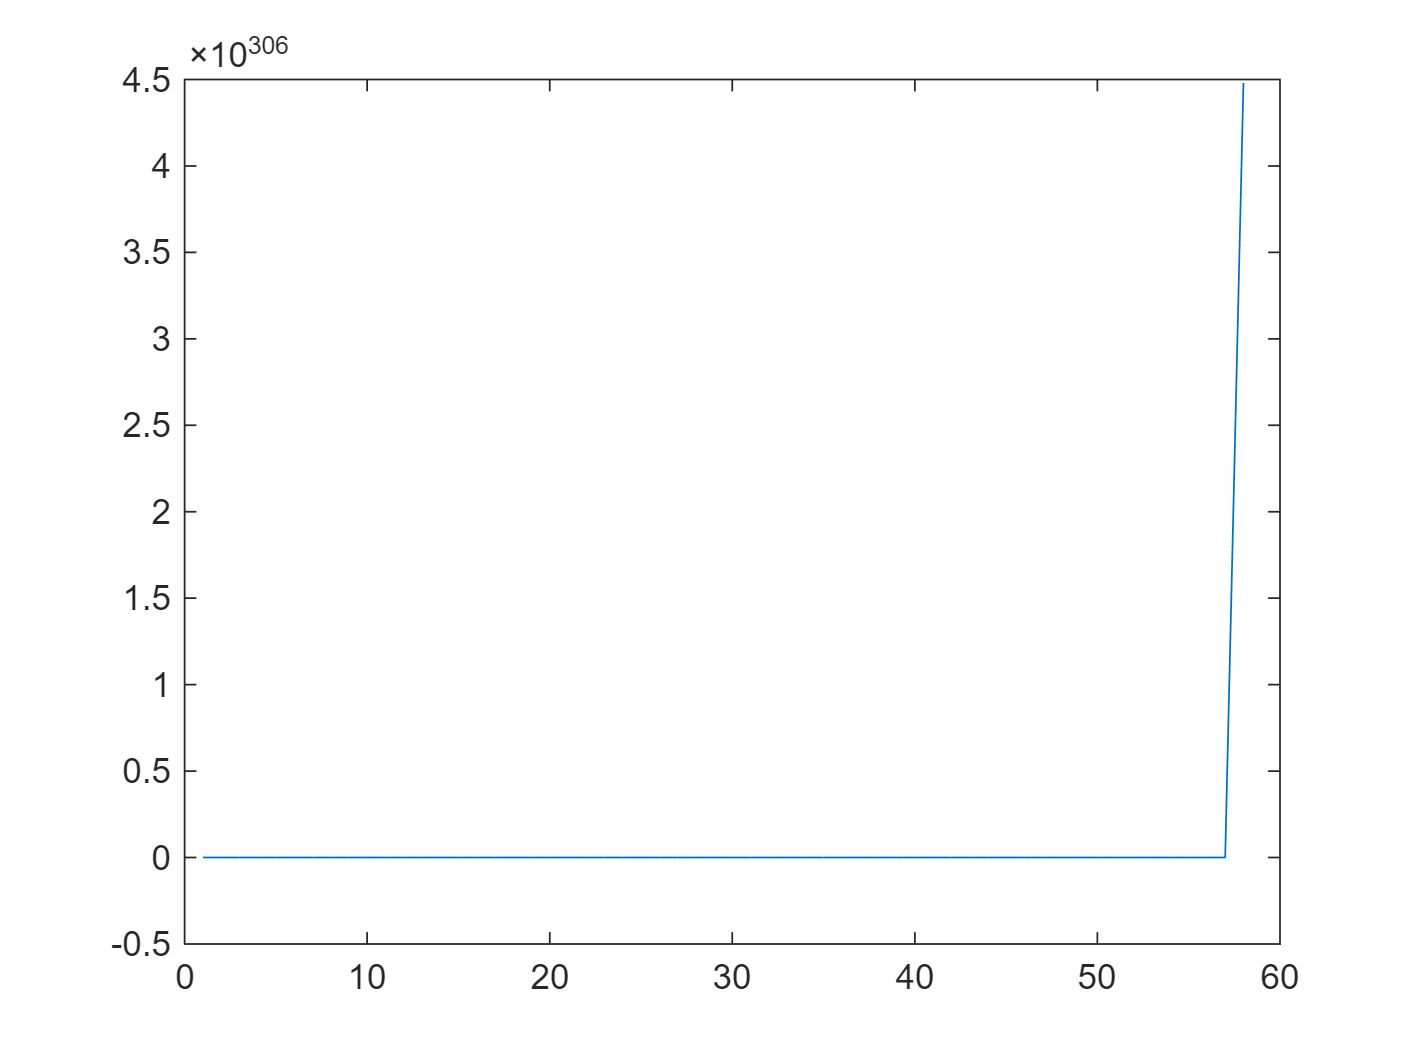

Y1=filter(num1,den2,A1);
plot(Y1)



function ownBode(x1,y1,fs)

N=length(x1);
X=fft(x1);
Y=fft(y1);
H=Y./X;
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-1);
figure
title('Bode diagram')
subplot(211)
semilogx(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')

xlim([10e3,10e6]);
ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
semilogx(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))
xlim([10e3,10e6]);

ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')
end